## **C/A code and Correlations **

clc;
clear all;
close all;
format long g;

## Task1

Generate the C/A code for the three satellites PRN A, PRN B and PRN C (see table below) following the description in the ICD200K, p.29ff together with table 3aI, p 4/5.

Crosscheck the first 10 chips of each of your generated codes with table 3-1 in the GPS interface specification (IS-GPS). Plot first 20 chips of the codes. 

One can find the link in below link : [https://www.gps.gov/technical/icwg/IS-GPS-200K.pdf]

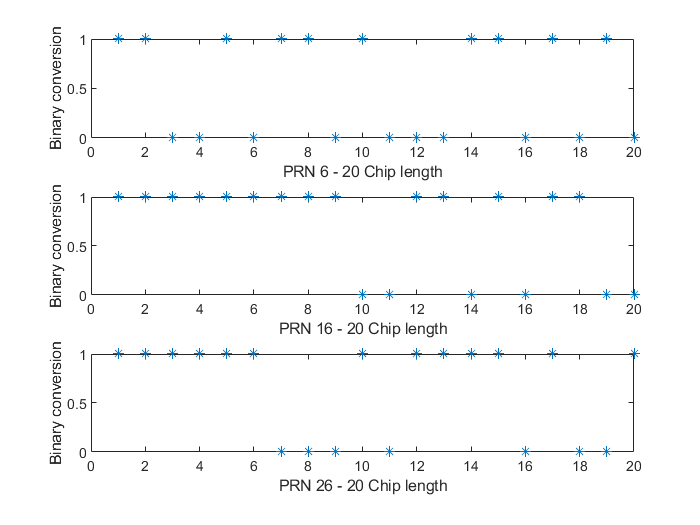

sv=[6;16;26];  % One has to enter the PRN/SV name as per requirements
g=cacode(sv);

CA1 = g(1,:);
CA2 = g(2,:);
CA3= g(3,:);
PRNA = CA1;
PRNB = CA2;
PRNC = CA3;

figure()
subplot(3,1,1)
axis tight
plot(g(1,1:20),'*');
xlabel('PRN 6 - 20 Chip length')
ylabel('Binary conversion')

subplot(3,1,2)
plot(g(2,1:20),'*');
xlabel('PRN 16 - 20 Chip length')
ylabel('Binary conversion')

subplot(3,1,3)
plot(g(3,1:20),'*');
xlabel('PRN 26 - 20 Chip length')
ylabel('Binary conversion')

## Task 2

Calculate the auto-correlation function of the code of PRN A and plot it between -022 and + 1022. What special characteristics of this function do you recognise?

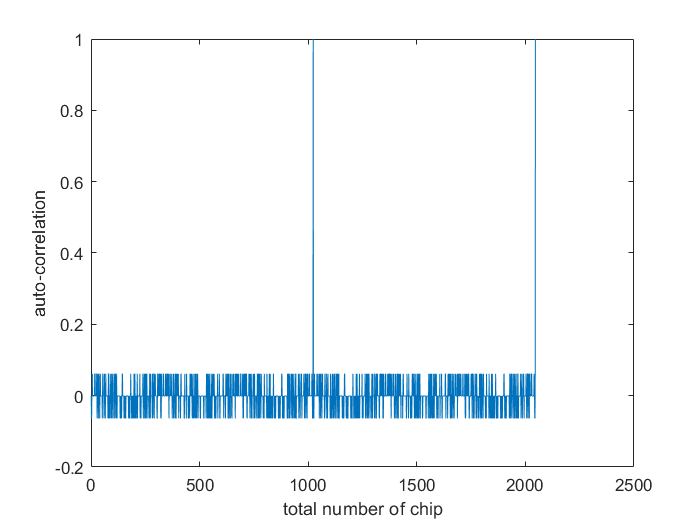

CA1=g(1,:);           %for the PRN6
CA2=g(2,:);           %for the PRN16
[Autocorr] = crosscorr(CA1, CA1);

%according to required result and below are according to the matlab
   figure();
   plot(Autocorr);
   xlabel('total number of chip');  %%i have started the x-axis with 0 scale integers to 2000 not like integers
   ylabel('auto-correlation');

## Task 3

Calculate the cross-correlation functions of the code of PRN A with each of the other codes. Plot them and specify their values for PRN A shifted about 0 and about 132 chips. What do you realise?

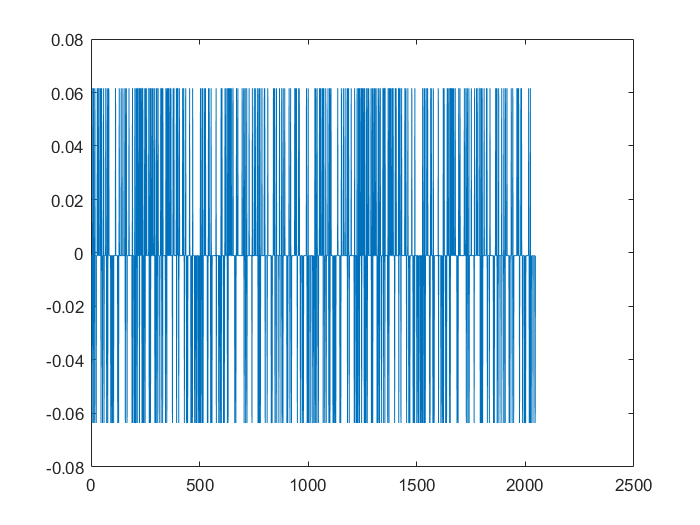

CA1=g(1,:);                             % for the PRN 6
CA2=g(2,:);                             % for the PRN 16
CA3=g(3,:);                             % for the PRN26
[Autocorr_1] = autocorrelation(CA1,CA2);
[Autocorr_2] = autocorrelation(CA2,CA3);
[Autocorr_3] = autocorrelation(CA1,CA3);

   figure()
   plot(Autocorr_1);   

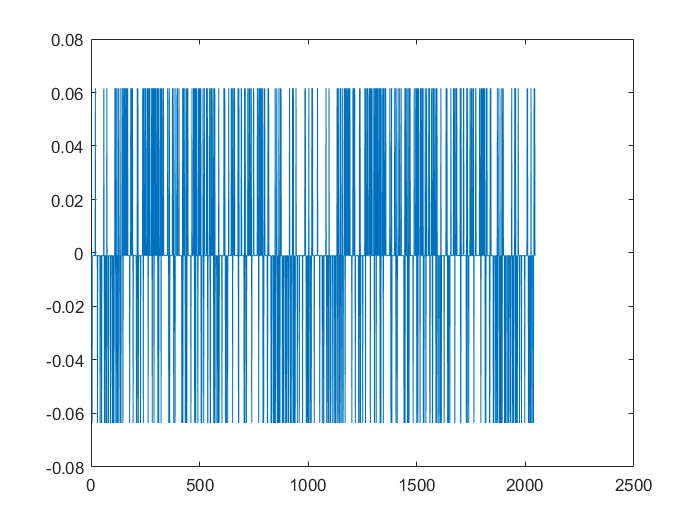

  
   figure()
   plot(Autocorr_2);    %red lines

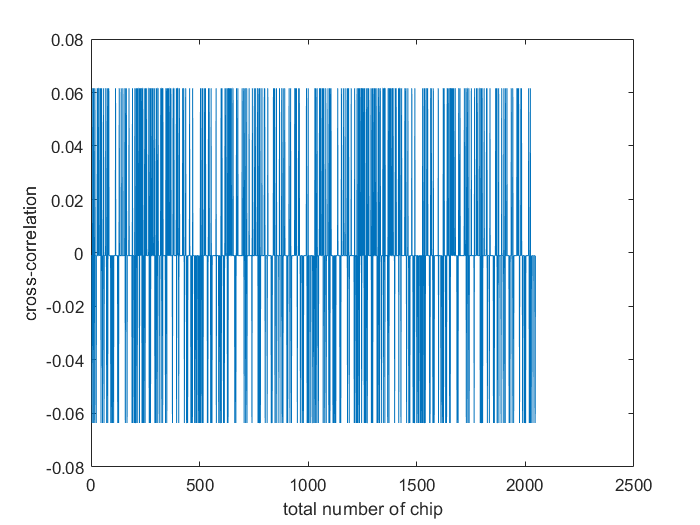

   
   figure()
   plot(Autocorr_1);   %blue lines
   
   
   xlabel('total number of chip');  %%i have started the x-axis with 0 scalingto 2000 not lilke integers
   ylabel('cross-correlation');

## Task 4

Let x1 be the code of PRN A shifted about 245 chips, let x2 be the code of PRN B shifted about 33 chips and let x3 be the code of PRN C shifted about 695 chips. Then set x = x1+ x2 + x3. Calculate the cross-correlation function of the accumulated code x with the original code of PRN A and plot it. What do you realise?

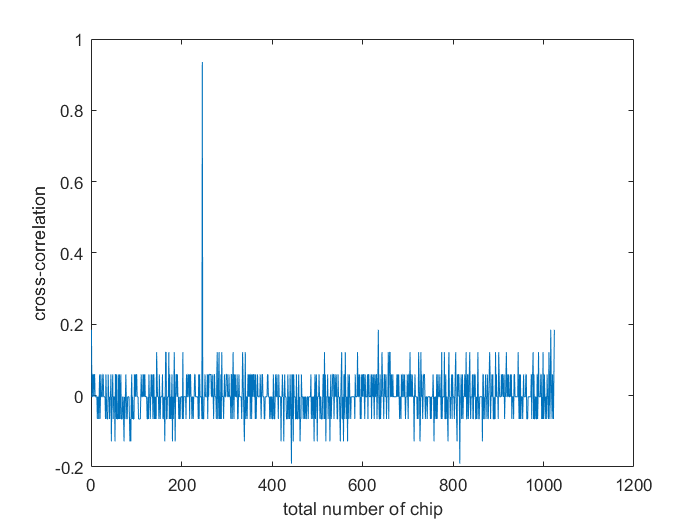

   sv=[6;16;26];

   % we have to convert range from (-1 to 1) from (1 to 1)
   g1=CA1;
   g1(1,g1==1)=-1;
   g1(1,g1==0)=1;
   g1=[g1 g1];

   g2=CA2;
   g2(1,g2==1)=-1;
   g2(1,g2==0)=1;
   g2=[g2 g2];

   g3=CA3;
   g3(1,g3==1)=-1;
   g3(1,g3==0)=1;
   g3=[g3 g3];

   g_1=g1(1,246:1023+245);
   g_2=g2(1,34:1023+33);
   g_3=g3(1,696:1023+695);
   g_new=g_1+g_2+g_3;

   [Autocorr_4] = cross_corr(g_new,[PRNA PRNA]);
   figure()
   plot(Autocorr_4);
   xlabel('total number of chip');  %%i have started the x-axis with 0 scalingto 2000 not lilke integers
   ylabel('cross-correlation');

   %it is cyclic code so the it will repeat after 1023 chip
   

## Task 5

Generate white noise with a standard deviation of 3 and add it to x. Then again calculate the cross-correlation function of this noisy signal with the original code of PRN A and plot it. What is different from the outcome of task 4?

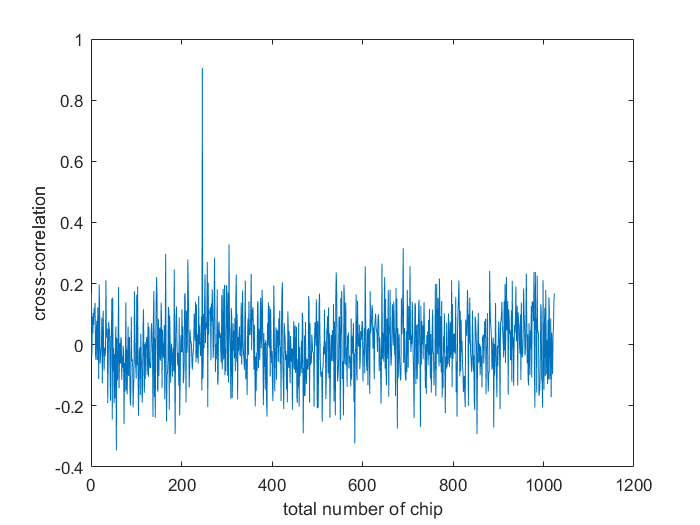

   deviation=randn(1,1023)*3;
   g_new=g_1+g_2+g_3+deviation;
   [Autocorr_5] = cross_corr(g_new,[PRNA PRNA]);
   figure()
   plot(Autocorr_5);
   xlabel('total number of chip');  %%i have started the x-axis with 0 scalingto 2000 not lilke integers
   ylabel('cross-correlation');

## Task 6

Discuss the investigated characteristics of the correlation functions with respect to the tracking performance of a GPS receiver. Up to which level of noise can the correlation peak be recognised?

Case 1

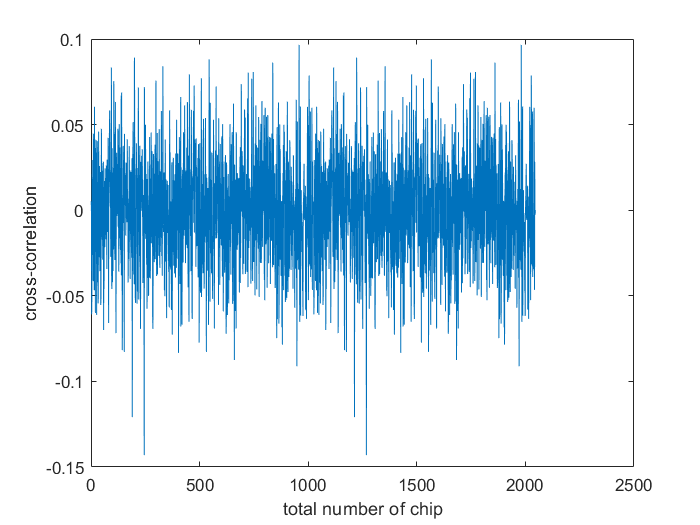

   deviation=randn(1,1023)*6;
   g_new=g_1+g_2+g_3+deviation;
   [Autocorr_6] = autocorrelation(g_new,[PRNA PRNA]);
   figure()
   plot(Autocorr_6);
   xlabel('total number of chip');  %%i have started the x-axis with 0 scalingto 2000 not lilke integers
   ylabel('cross-correlation');

   Case 2

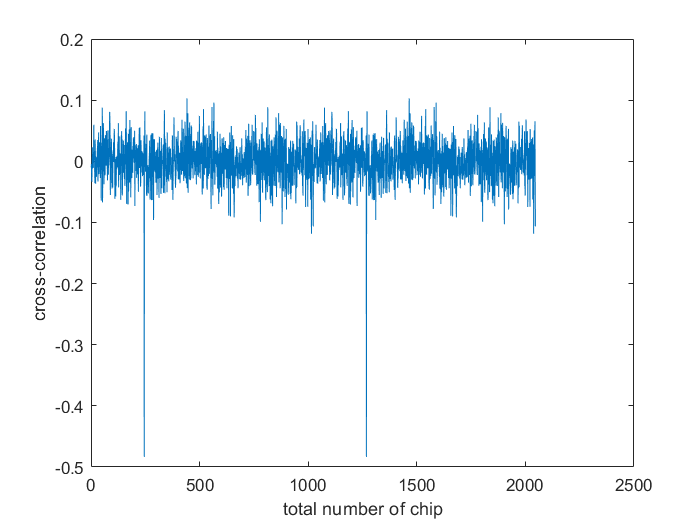

   deviation=randn(1,1023)*1;
   g_new=g_1+g_2+g_3+deviation;
   [Autocorr_6_2] = autocorrelation(g_new,[PRNA PRNA]);
   figure()
   plot(Autocorr_6_2);
   xlabel('total number of chip');  %%i have started the x-axis with 0 scalingto 2000 not lilke integers
   ylabel('cross-correlation');

function g=cacode(PRN)
% Generates 1023 length C/A Codes for GPS PRNs 1-37
% g: nx1023 matrix- with each PRN in each row with symbols 1 and 0
% PRN: a row or column vector of the PRN's to be generated
%
if nargin<2
end

if (max(PRN)>37) || (min(PRN)<1) || (min(size(PRN))~=1)
	error('PRN must be a row or column vector between 1 and 37')
end

% table of C/A Code Phase Selection (sets delay for G2 generator)
SEL=[2 6;    3 7;    4 8;    5 9;    1 9;    2 10;    1 8;    2 9;
     3 10;   2 3;    3 4;    5 6;    6 7;    7 8;     8 9;    9 10;
     1 4;    2 5;    3 6;    4 7;    5 8;    6 9;     1 3;    4 6;
     5 7;    6 8;    7 9;    8 10;   1 6;    2 7;     3 8;    4 9
     5 10;   4 10;   1 7;    2 8;    4 10];

% G1 Sequence: 1+x^3+x^10
% Initial value for G1
init=[0 0 1 0 0 0 0 0 0 1];
n1=length(init);
G1=ones(1,n1);	

% G2 Sequence: 1+x^2+x^3+x^6+x^8+x^9+x^10
% Initial value for G2
init2=[0 1 1 0 0 1 0 1 1 1];
n2=length(init2);
G2=ones(1,n2);	

L=2^n1-1;
% C/A Code generation:
Pha_sel=SEL(PRN,:);
for inc=1:L
    g2(:,inc)=mod(sum(G2(Pha_sel),2),2);
     g(:,inc)=mod(G1(n1)+g2(:,inc),2);
   G1=[mod(sum(G1.*init),2) G1(1:n1-1)];
   G2=[mod(sum(G2.*init2),2) G2(1:n2-1)];
end
end

function [Autocorr] = crosscorr(CA1, CA2)

CA1_m = CA1- mean(CA1);
CA2 = [CA2, CA2, CA2];
CA2_m = CA2- mean(CA2);
Autocorr=[];
for i = 1: length(CA1)*2
    temp = 0;
    sum_x = 0;
    sum_y= 0;
    for j = 1:1023
        temp = temp + (CA1_m(j) * CA2_m(j+i));
        sum_x = sum_x + CA1_m(j)^2;
        sum_y = sum_y + CA2_m(j)^2;
    end
    Autocorr = [Autocorr; temp/sqrt(sum_x*sum_y)];
    
end

end

function [Autocorr] = autocorrelation(CA1, CA2)

CA1_m = CA1- mean(CA1);
CA2 = [CA2, CA2, CA2];
CA2_m = CA2- mean(CA2);
Autocorr=[];
for i = 1: length(CA1)*2
    temp = 0;
    sum_x = 0;
    sum_y= 0;
    for j = 1:1023
        temp = temp + (CA1_m(j) * CA2_m(j+i));
        sum_x = sum_x + CA1_m(j)^2;
        sum_y = sum_y + CA2_m(j)^2;
    end
    Autocorr = [Autocorr; temp/sqrt(sum_x*sum_y)];
end
end

function [Autocorr] = cross_corr(g_new,CA1)
CA1=[CA1 CA1];
CA2 =g_new(1,1:1023);
CA1(1,CA1 == 1) = -1;
CA1(1,CA1 == 0) = 1;
Autocorr = zeros(1,1024);
for i = 0:1:1023
Autocorr(i+1) = CA1(1,i+1:i+1023)*(CA2')/1023;
end

end

